# **Nonlinear Dynamic MATLAB Substructure**

This example demonstrates a nonlinear dynamic MATLAB substructure under sinusoidal loading.

The physical system is a single-degree-of-freedom Duffing oscillator:

$$

mu'' + cu' + k u + \alpha u^3 = P_0 \sin(\omega t)

$$

OpenSees performs the transient analysis using the Newmark method. The MATLAB callback returns the nonlinear internal force, consistent tangent stiffness, mass matrix, and damping matrix.

An independent [ode45 - Solve nonstiff differential equations — medium order method - MATLAB](https://www.mathworks.com/help/matlab/ref/ode45.html) solution is used as a reference.

clc; clear; close all;

% Model parameters
m = 2.0;
c = 1.5;
k = 400.0;
alpha = 2.0e6;

P0 = 20.0;
frequency = 2.0;
omega = 2*pi*frequency;

dt = 0.001;
duration = 5.0;
nSteps = round(duration/dt);

time = (0:nSteps).' * dt;
loadValues = P0*sin(omega*time);

K0 = k * [
     1 -1
    -1  1
];

% Only node 2 carries physical mass and damping.
M0 = [
    0 0
    0 m
];

C0 = [
    0 0
    0 c
];

initialState = struct( ...
    "k", k, ...
    "alpha", alpha, ...
    "M", M0, ...
    "C", C0);

%% Create the OpenSees command interface

opsMAT = OpenSeesMatlab();
ops = opsMAT.opensees;

% Remove a model left by an earlier run.
ops.wipe();

% Automatically clean up if the script stops because of an error.
cleanupGuard = onCleanup( ...
    @() cleanupNonlinearDynamicModel(ops));

%% Create nodes and boundary conditions
%
%   fixed node 1 ---- nonlinear substructure ---- node 2
%
% Both nodes have one translational DOF.

ops.model("basic", "-ndm", 1, "-ndf", 1);

ops.node(1, 0.0);
ops.node(2, 1.0);

ops.fix(1, 1);

%% Define the interface
% Each row is:
%
%   [nodeTag, oneBasedDOF]
%
% The row order defines trial.disp, trial.vel, trial.accel,
% response.force, and all returned matrix rows and columns.

interfacePairs = [
    1 1
    2 1
];

eleTag = 2001;

ops.matlabSubstructure( ...
    eleTag, ...
    @duffingSubstructureCallback, ...
    initialState, ...
    K0, ...
    interfacePairs, ...
    "tangentMode", "matlab");

% Do not also assign mass m using ops.mass(). The physical mass is already
% returned by the MATLAB callback.

%% Create the sinusoidal external load
% loadValues already contains the value at t = 0. Therefore,
% "-prependZero" must not be used, or the loading history will be shifted
% by one time step.

timeSeriesTag = 1;
patternTag = 1;

ops.timeSeries( ...
    "Path", ...
    timeSeriesTag, ...
    "-dt", dt, ...
    "-values", loadValues.');

ops.pattern( ...
    "Plain", ...
    patternTag, ...
    timeSeriesTag);

% A unit reference load is multiplied by the Path time-series factor.
ops.load(2, 1.0);

%% Configure the nonlinear transient analysis

ops.constraints("Plain");
ops.numberer("Plain");
ops.system("BandGeneral");

ops.test( ...
    "EnergyIncr", ...
    1.0e-12, ...
    30);

ops.algorithm("Newton");

% Average-acceleration Newmark method.
gamma = 0.5;
beta = 0.25;

ops.integrator( ...
    "Newmark", ...
    gamma, ...
    beta);

ops.analysis("Transient");

%% Allocate response arrays

uOpenSees = zeros(nSteps + 1, 1);
vOpenSees = zeros(nSteps + 1, 1);
aOpenSees = zeros(nSteps + 1, 1);
forceOpenSees = zeros(nSteps + 1, 1);

analysisStatus = zeros(nSteps, 1);

% Initial nodal response.
uOpenSees(1) = ops.nodeDisp(2, 1);
vOpenSees(1) = ops.nodeVel(2, 1);
aOpenSees(1) = ops.nodeAccel(2, 1);

% The Element may not have been initialized before the first analysis
% update. The initial nonlinear elastic force is zero for this example.
forceOpenSees(1) = 0.0;

%% Run the transient analysis
% One time step can contain several callback evaluations. The callback must
% therefore calculate every trial from committedState.

failedStep = 0;

for step = 1:nSteps

    analysisStatus(step) = ops.analyze(1, dt);

    if analysisStatus(step) ~= 0
        failedStep = step;
        break
    end

    index = step + 1;

    uOpenSees(index) = ops.nodeDisp(2, 1);
    vOpenSees(index) = ops.nodeVel(2, 1);
    aOpenSees(index) = ops.nodeAccel(2, 1);

    interfaceForce = ops.eleResponse( ...
        eleTag, ...
        "interfaceForce");

    forceOpenSees(index) = interfaceForce(end);
end

if failedStep ~= 0
    error( ...
        "The nonlinear transient analysis failed at step %d, time %.6f s.", ...
        failedStep, ...
        failedStep*dt);
end

%% Independent ode45 reference solution
% Solve:
%
%   m*u'' + c*u' + k*u + alpha*u^3 = P0*sin(omega*t)

odeFunction = @(t,y) [
    y(2)
    (P0*sin(omega*t) ...
        - c*y(2) ...
        - k*y(1) ...
        - alpha*y(1)^3) / m
];

odeOptions = odeset( ...
    "RelTol", 1.0e-10, ...
    "AbsTol", 1.0e-12);

initialConditions = [
    0
    0
];

[timeReference, stateReference] = ode45( ...
    odeFunction, ...
    time, ...
    initialConditions, ...
    odeOptions);

uReference = stateReference(:,1);
vReference = stateReference(:,2);

aReference = ( ...
    loadValues ...
    - c*vReference ...
    - k*uReference ...
    - alpha*uReference.^3) / m;

% The Element interface force excludes the separately assembled C*v term.
forceReference = ...
    k*uReference + alpha*uReference.^3;

%% Calculate verification errors

displacementDifference = ...
    uOpenSees - uReference;

velocityDifference = ...
    vOpenSees - vReference;

accelerationDifference = ...
    aOpenSees - aReference;

forceDifference = ...
    forceOpenSees - forceReference;

maxDisplacementError = ...
    max(abs(displacementDifference));

rmsDisplacementError = ...
    sqrt(mean(displacementDifference.^2));

maxVelocityError = ...
    max(abs(velocityDifference));

rmsVelocityError = ...
    sqrt(mean(velocityDifference.^2));

maxAccelerationError = ...
    max(abs(accelerationDifference));

rmsAccelerationError = ...
    sqrt(mean(accelerationDifference.^2));

maxForceError = ...
    max(abs(forceDifference));

rmsForceError = ...
    sqrt(mean(forceDifference.^2));

maxDisplacement = ...
    max(abs(uOpenSees));

maxVelocity = ...
    max(abs(vOpenSees));

maxAcceleration = ...
    max(abs(aOpenSees));

maxRestoringForce = ...
    max(abs(forceOpenSees));

displacementScale = ...
    max(max(abs(uReference)), 1.0e-12);

forceScale = ...
    max(max(abs(forceReference)), 1.0e-12);

relativeDisplacementError = ...
    maxDisplacementError / displacementScale;

relativeForceError = ...
    maxForceError / forceScale;

%% Verify the numerical agreement
% Newmark and ode45 use different integration methods, so their solutions
% are not expected to be identical.

absoluteDisplacementTolerance = 2.0e-4;
relativeDisplacementTolerance = 1.0e-2;

verificationPassed = ...
    maxDisplacementError <= absoluteDisplacementTolerance || ...
    relativeDisplacementError <= relativeDisplacementTolerance;

if ~verificationPassed

    errorMessage = sprintf( ...
        "Displacement verification failed.\n" + ...
        "Maximum absolute error: %.6e\n" + ...
        "Maximum reference response: %.6e\n" + ...
        "Relative error: %.6e\n" + ...
        "Absolute tolerance: %.6e\n" + ...
        "Relative tolerance: %.6e", ...
        maxDisplacementError, ...
        displacementScale, ...
        relativeDisplacementError, ...
        absoluteDisplacementTolerance, ...
        relativeDisplacementTolerance);

    error("%s", errorMessage);
end

%% Read callback statistics

trialCalls = ops.eleResponse( ...
    eleTag, ...
    "trialCallCount");

totalCalls = ops.eleResponse( ...
    eleTag, ...
    "callCount");

commitCount = ops.eleResponse( ...
    eleTag, ...
    "commitCount");

totalCallbackTime = ops.eleResponse( ...
    eleTag, ...
    "callbackTime");

meanCallbackTime = ops.eleResponse( ...
    eleTag, ...
    "meanCallbackTime");

maxCallbackTime = ops.eleResponse( ...
    eleTag, ...
    "maxCallbackTime");

%% Print one consolidated report

reportFormat = ...
    "\n" + ...
    "============================================================\n" + ...
    " Nonlinear Dynamic MATLAB Substructure Verification\n" + ...
    "============================================================\n" + ...
    "System parameters\n" + ...
    "  Mass                         : %.6g\n" + ...
    "  Damping                      : %.6g\n" + ...
    "  Linear stiffness             : %.6g\n" + ...
    "  Cubic stiffness              : %.6g\n" + ...
    "  Force amplitude              : %.6g\n" + ...
    "  Loading frequency            : %.6g Hz\n" + ...
    "  Time step                    : %.6g s\n" + ...
    "  Duration                     : %.6g s\n" + ...
    "  Number of steps              : %d\n" + ...
    "\n" + ...
    "Peak OpenSees response\n" + ...
    "  Maximum |displacement|       : %.6e\n" + ...
    "  Maximum |velocity|           : %.6e\n" + ...
    "  Maximum |acceleration|       : %.6e\n" + ...
    "  Maximum |restoring force|    : %.6e\n" + ...
    "\n" + ...
    "OpenSees versus ode45\n" + ...
    "  Maximum displacement error   : %.6e\n" + ...
    "  RMS displacement error       : %.6e\n" + ...
    "  Relative displacement error  : %.6e\n" + ...
    "  Maximum velocity error       : %.6e\n" + ...
    "  RMS velocity error           : %.6e\n" + ...
    "  Maximum acceleration error   : %.6e\n" + ...
    "  RMS acceleration error       : %.6e\n" + ...
    "  Maximum force error          : %.6e\n" + ...
    "  RMS force error              : %.6e\n" + ...
    "  Relative force error         : %.6e\n" + ...
    "\n" + ...
    "Callback statistics\n" + ...
    "  Trial calls                  : %.0f\n" + ...
    "  Total calls                  : %.0f\n" + ...
    "  Committed steps              : %.0f\n" + ...
    "  Total callback time          : %.6e s\n" + ...
    "  Mean callback time           : %.6e s\n" + ...
    "  Maximum callback time        : %.6e s\n" + ...
    "\n" + ...
    "Verification status            : PASSED\n" + ...
    "============================================================\n";

report = sprintf( ...
    reportFormat, ...
    m, ...
    c, ...
    k, ...
    alpha, ...
    P0, ...
    frequency, ...
    dt, ...
    duration, ...
    nSteps, ...
    maxDisplacement, ...
    maxVelocity, ...
    maxAcceleration, ...
    maxRestoringForce, ...
    maxDisplacementError, ...
    rmsDisplacementError, ...
    relativeDisplacementError, ...
    maxVelocityError, ...
    rmsVelocityError, ...
    maxAccelerationError, ...
    rmsAccelerationError, ...
    maxForceError, ...
    rmsForceError, ...
    relativeForceError, ...
    trialCalls, ...
    totalCalls, ...
    commitCount, ...
    totalCallbackTime, ...
    meanCallbackTime, ...
    maxCallbackTime);

fprintf("%s", report);


 Nonlinear Dynamic MATLAB Substructure Verification
System parameters
  Mass                         : 2
  Damping                      : 1.5
  Linear stiffness             : 400
  Cubic stiffness              : 2e+06
  Force amplitude              : 20
  Loading frequency            : 2 Hz
  Time step                    : 0.001 s
  Duration                     : 5 s
  Number of steps              : 5000

Peak OpenSees response
  Maximum |displacement|       : 3.046087e-02
  Maximum |velocity|           : 5.177169e-01
  Maximum |acceleration|       : 2.435884e+01
  Maximum |restoring force|    : 6.871147e+01

OpenSees versus ode45
  Maximum displacement error   : 1.015485e-05
  RMS displacement error       : 4.343341e-06
  Relative displacement error  : 3.333661e-04
  Maximum velocity error       : 2.968489e-04
  RMS velocity error           : 1.113563e-04
  Maximu

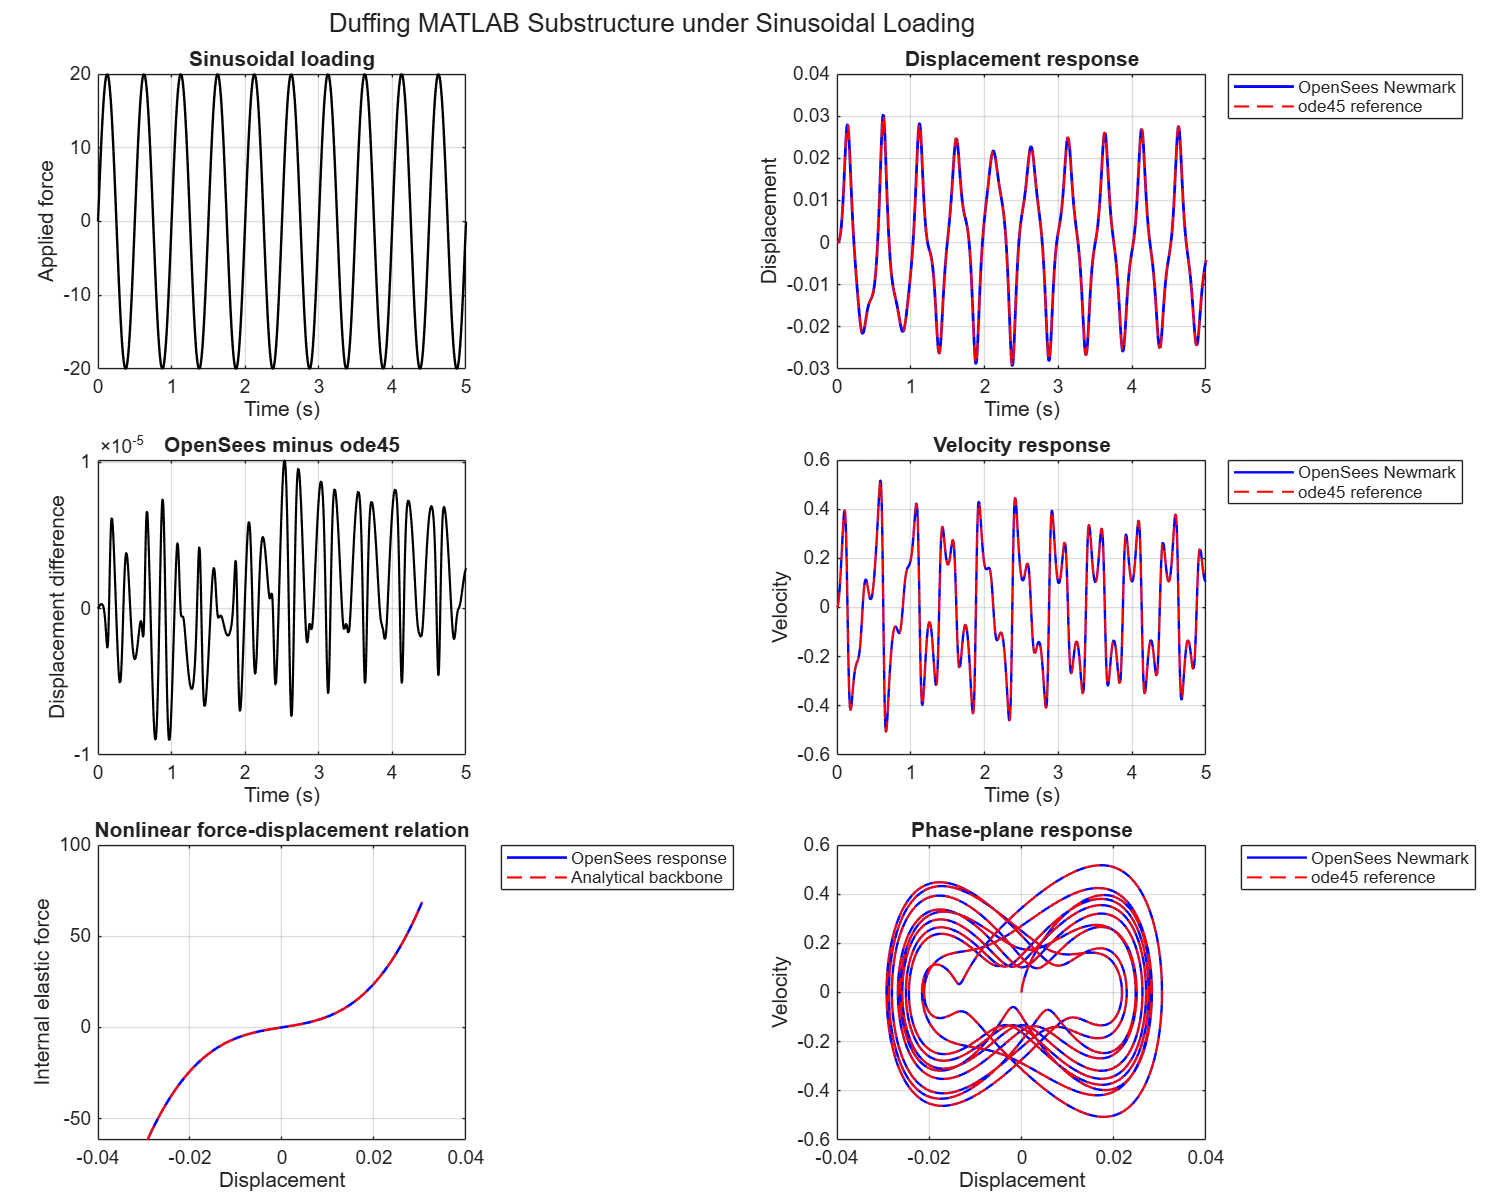

%% Plot the results

f=figure( ...
    "Name", ...
    "Nonlinear Dynamic Substructure Verification", ...
    "Color", ...
    "w");
f.Position = [100 200 1000 800];

tiledlayout( ...
    3, ...
    2, ...
    "TileSpacing", ...
    "compact", ...
    "Padding", ...
    "compact");

% Sinusoidal loading
nexttile;

plot( ...
    time, ...
    loadValues, ...
    "k-", ...
    "LineWidth", ...
    1.2);

grid on;
box on;

xlabel("Time (s)");
ylabel("Applied force");
title("Sinusoidal loading");

% Displacement comparison
nexttile;

plot( ...
    time, ...
    uOpenSees, ...
    "b-", ...
    "LineWidth", ...
    1.4);

hold on;

plot( ...
    timeReference, ...
    uReference, ...
    "r--", ...
    "LineWidth", ...
    1.1);

hold off;
grid on;
box on;

xlabel("Time (s)");
ylabel("Displacement");
title("Displacement response");

legend( ...
    "OpenSees Newmark", ...
    "ode45 reference", ...
    "Location", ...
    "bestoutside");

% Displacement difference
nexttile;

plot( ...
    time, ...
    displacementDifference, ...
    "k-", ...
    "LineWidth", ...
    1.1);

grid on;
box on;

xlabel("Time (s)");
ylabel("Displacement difference");
title("OpenSees minus ode45");

% Velocity comparison
nexttile;

plot( ...
    time, ...
    vOpenSees, ...
    "b-", ...
    "LineWidth", ...
    1.2);

hold on;

plot( ...
    timeReference, ...
    vReference, ...
    "r--", ...
    "LineWidth", ...
    1.0);

hold off;
grid on;
box on;

xlabel("Time (s)");
ylabel("Velocity");
title("Velocity response");

legend( ...
    "OpenSees Newmark", ...
    "ode45 reference", ...
    "Location", ...
    "bestoutside");

% Nonlinear force-displacement relation
nexttile;

plot( ...
    uOpenSees, ...
    forceOpenSees, ...
    "b-", ...
    "LineWidth", ...
    1.3);

hold on;

uBackbone = linspace( ...
    min(uOpenSees), ...
    max(uOpenSees), ...
    400).';

forceBackbone = ...
    k*uBackbone + alpha*uBackbone.^3;

plot( ...
    uBackbone, ...
    forceBackbone, ...
    "r--", ...
    "LineWidth", ...
    1.1);

hold off;
grid on;
box on;

xlabel("Displacement");
ylabel("Internal elastic force");
title("Nonlinear force-displacement relation");

legend( ...
    "OpenSees response", ...
    "Analytical backbone", ...
    "Location", ...
    "bestoutside");

% Phase-plane response
nexttile;

plot( ...
    uOpenSees, ...
    vOpenSees, ...
    "b-", ...
    "LineWidth", ...
    1.2);

hold on;

plot( ...
    uReference, ...
    vReference, ...
    "r--", ...
    "LineWidth", ...
    1.0);

hold off;
grid on;
box on;

xlabel("Displacement");
ylabel("Velocity");
title("Phase-plane response");

legend( ...
    "OpenSees Newmark", ...
    "ode45 reference", ...
    "Location", ...
    "bestoutside");

sgtitle( ...
    "Duffing MATLAB Substructure under Sinusoidal Loading");

%% Clean up
% Query all results before cleanup.
%
% Correct cleanup order:
%
%   1. Remove active Elements with ops.wipe().
%   2. Remove MATLAB callback records.

ops.wipe();
ops.clearMatlabSubstructures();

clear cleanupGuard

%% Nonlinear MATLAB callback
% The relative displacement is:
%
%   relativeDisp = u2 - u1
%
% The nonlinear elastic force is:
%
%   q = k*relativeDisp + alpha*relativeDisp^3
%
% The consistent tangent is:
%
%   kt = k + 3*alpha*relativeDisp^2

function [response, trialState, status] = ...
        duffingSubstructureCallback( ...
            action, ...
            trial, ...
            committedState)

    status = int32(0);

    % Every trial begins from the last state committed by OpenSees.
    trialState = committedState;

    switch lower(string(action))

        case {"init", "trial"}

            relativeDisp = ...
                trial.disp(2) - trial.disp(1);

            q = ...
                committedState.k*relativeDisp ...
                + committedState.alpha*relativeDisp^3;

            kt = ...
                committedState.k ...
                + 3*committedState.alpha*relativeDisp^2;

            % Internal resisting force in interfacePairs row order.
            response.force = [
                -q
                 q
            ];

            % Consistent derivative with respect to [u1; u2].
            response.tangent = kt * [
                 1 -1
                -1  1
            ];

            % OpenSees separately assembles M*a and C*v.
            response.mass = ...
                committedState.M;

            response.damping = ...
                committedState.C;

            if strcmpi(action, "init")

                response.initialStiffness = ...
                    committedState.k * [
                         1 -1
                        -1  1
                    ];

                response.initialMass = ...
                    committedState.M;

                response.initialDamping = ...
                    committedState.C;
            end

            % Candidate state. OpenSees accepts it only after convergence.
            trialState.relativeDisp = ...
                relativeDisp;

            trialState.force = ...
                q;

            trialState.time = ...
                trial.time;

        case { ...
                "commit", ...
                "revert", ...
                "reverttostart", ...
                "shutdown"}

            response = struct();

        otherwise

            response = struct();
            status = int32(-1);
    end
end

%% Cleanup helper

function cleanupNonlinearDynamicModel(ops)

    try
        ops.wipe();
    catch
    end

    try
        ops.clearMatlabSubstructures();
    catch
    end
end